# Lecture 16

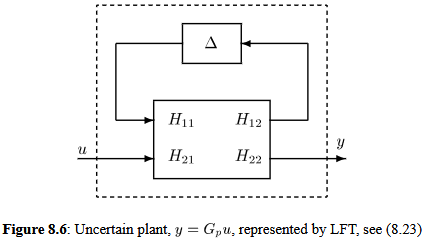

## Exercise 8.3

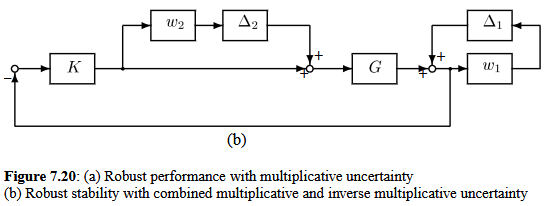 

syms I G K W1 W2

M = [W1*inv(I + G*K), W1*inv(I + G*K)*G;
     W2*inv(I + K*G)*K, W2*K*G*inv(I + K*G)]

$$H = \left(\begin{array}{cc} \frac{W_{1}}{\text{I}+G\,K} & \frac{G\,W_{1}}{\text{I}+G\,K}\\ \frac{K\,W_{2}}{\text{I}+G\,K} & \frac{G\,K\,W_{2}}{\text{I}+G\,K} \end{array}\right)$$

## Exercise 8.4

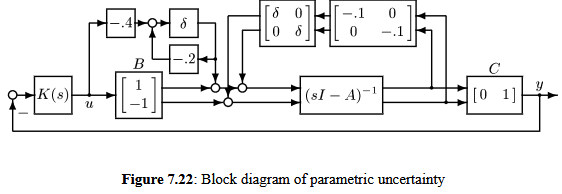

## Note: Exercsie 4

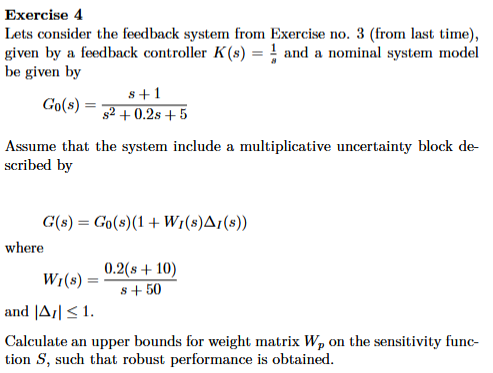

Robust performance condition: $|W_p S|+|W_I T|<1$

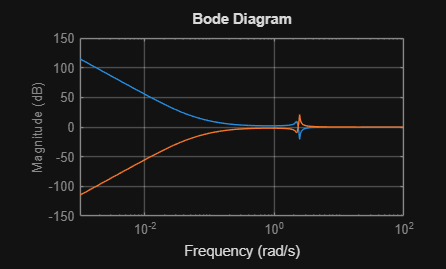

syms s
s = tf('s');

G0 = (s + 1) / (s^2 + 0.2*s + 5);
K = 1/s;

W_I = (0.2*s + 2) / (s + 50);
G = G0 + W_I;

L = G*K;
S = inv(1 + L);
T = L/S;
W_p = (1 - W_I*T)/S;

bodemag(W_p)
hold on
bodemag(1/W_p)
grid on
hold off

## Note: Exercsie 5

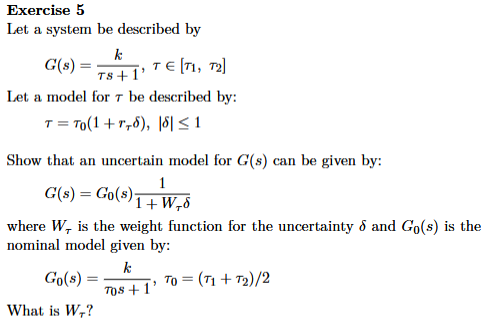

syms k tau0 s r_tau delta W_tau

tau = tau0*(1 + r_tau*delta);
G = k / (tau*s + 1)

$$G = \frac{k}{s\,\tau_{0}\,\left(\delta \,r_{\tau }+1\right)+1}$$

G0 = k / (tau0*s + 1);
W_tau = G0 / (1 + W_tau*delta)

$$W\_tau = \frac{k}{\left(W_{\tau }\,\delta +1\right)\,\left(s\,\tau_{0}+1\right)}$$